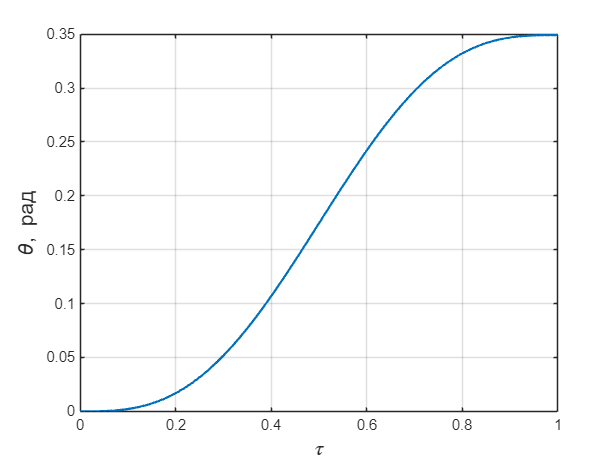

t = 0:0.01:10;
T = 4;
tau = t/T;
theta_total = deg2rad(20);

theta = theta_total*(tau - 1/(2*pi) * sin(2*pi * tau));


figure
plot(tau, theta,'LineWidth',1.5)
xlim([0,1])
grid on
xlabel('$\tau$','Interpreter','latex', 'FontSize',14)
ylabel("\theta, рад", "FontSize",14)
print(gcf, 'img/theta_sin.png', '-dpng', '-r600')

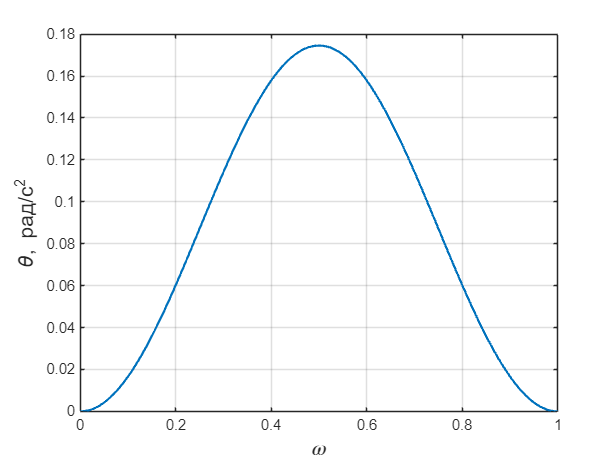

figure
omega = 2*theta_total/T .* sin(pi*tau).^2;
plot(tau, omega, 'LineWidth',1.5)
xlim([0,1])

grid on
xlabel('$\omega$','Interpreter','latex', 'FontSize',14)
ylabel("\theta, рад/c^2", "FontSize",14)
print(gcf, 'img/omega_sin.png', '-dpng', '-r600')

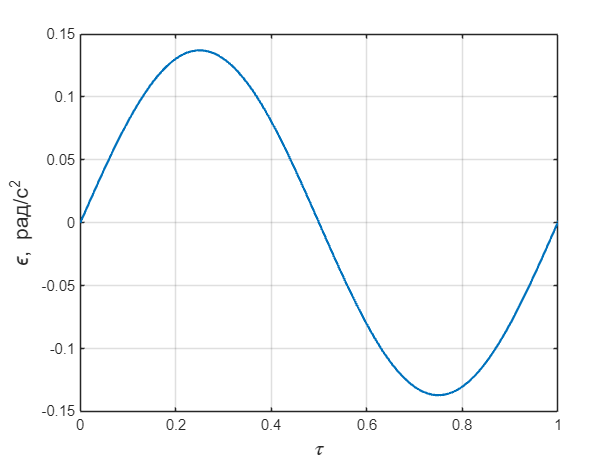

eps = 2*pi * theta_total/T^2 * sin(2*pi*tau);
figure
plot(tau, eps, LineWidth=1.5)
xlim([0,1])
grid on
xlabel('$\tau$','Interpreter','latex', 'FontSize',14)
ylabel("\epsilon, рад/c^2", "FontSize",14)
print(gcf, 'img/eps_sin.png', '-dpng', '-r600')

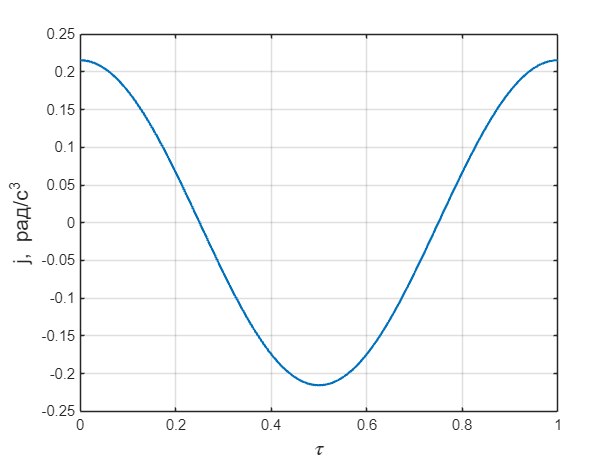


figure
j = 4*pi^2*theta_total/T^3 * cos(2*pi * tau);
plot(tau, j,'LineWidth',1.5)
xlim([0,1])
xlabel('$\tau$','Interpreter','latex', 'FontSize',14)
grid on
ylabel("j, рад/c^3", "FontSize",14)
print(gcf, 'img/jerk_sin.png', '-dpng', '-r600')

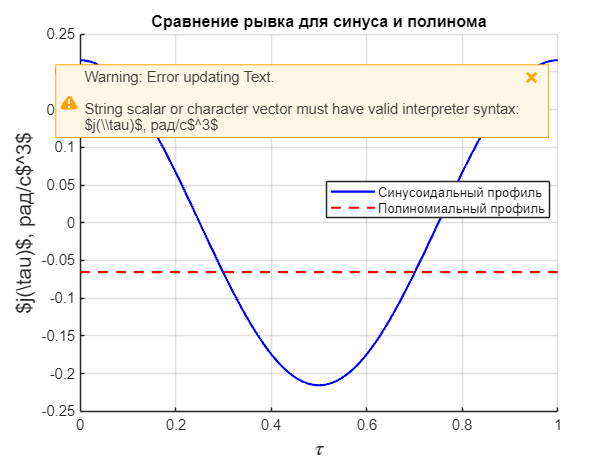


theta_total = deg2rad(20);   % угол поворота, рад
T = 4;             % время разгона
tau = linspace(0,1,1000); % нормированное время

% --- СИНУСОИДАЛЬНЫЙ ПРОФИЛЬ ---
% закон угла
theta_sin = theta_total*(tau - 1/(2*pi)*sin(2*pi*tau));
% угловая скорость
omega_sin = (2*theta_total/T)*sin(pi*tau).^2;
% ускорение
alpha_sin = (2*pi*theta_total/T^2)*sin(2*pi*tau);
% рывок
j_sin = (4*pi^2*theta_total/T^3)*cos(2*pi*tau);

% --- ПОЛИНОМИАЛЬНЫЙ ПРОФИЛЬ (кубический: 3tau^2 - 2tau^3) ---
theta_poly = theta_total*(3*tau.^2 - 2*tau.^3);
omega_poly = (theta_total/T)*(6*tau - 6*tau.^2);
alpha_poly = (theta_total/T^2)*(6 - 12*tau);
j_poly = (theta_total/T^3)*(-12*ones(size(tau)));

% --- ВИЗУАЛИЗАЦИЯ ---
figure; hold on; grid on;
plot(tau, j_sin, 'b-', 'LineWidth',1.5, 'DisplayName','Синусоидальный профиль');
plot(tau, j_poly, 'r--', 'LineWidth',1.5, 'DisplayName','Полиномиальный профиль');
xlabel('$\tau$','Interpreter','latex','FontSize',14);
ylabel('$j(\tau)$, рад/с$^3$','Interpreter','latex','FontSize',14);
legend('Location','Best');
title('Сравнение рывка для синуса и полинома');

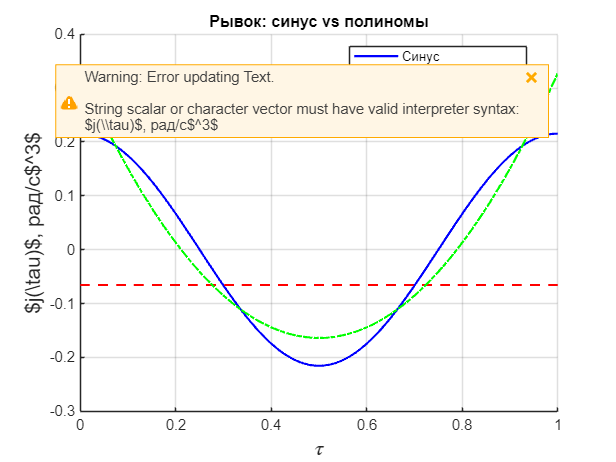


% --- КВИНТИК (minimum-jerk) ---
theta_q5 = theta_total*(10*tau.^3 - 15*tau.^4 + 6*tau.^5);
omega_q5 = (theta_total/T)*(30*tau.^2 - 60*tau.^3 + 30*tau.^4);
alpha_q5 = (theta_total/T^2)*(60*tau - 180*tau.^2 + 120*tau.^3);
j_q5     = (theta_total/T^3)*(60 - 360*tau + 360*tau.^2);

% --- ПЛОТ РЫВКА ---
figure; hold on; grid on;
plot(tau, j_sin,  'b-',  'LineWidth',1.5, 'DisplayName','Синус');
plot(tau, j_poly, 'r--', 'LineWidth',1.5, 'DisplayName','Кубик 3-2-1 (const j)');
plot(tau, j_q5,   'g-.', 'LineWidth',1.5, 'DisplayName','Квинтик (min-jerk)');

xlabel('$\tau$','Interpreter','latex','FontSize',14);
ylabel('$j(\tau)$, рад/с$^3$','Interpreter','latex','FontSize',14);
legend('Location','Best');
title('Рывок: синус vs полиномы');

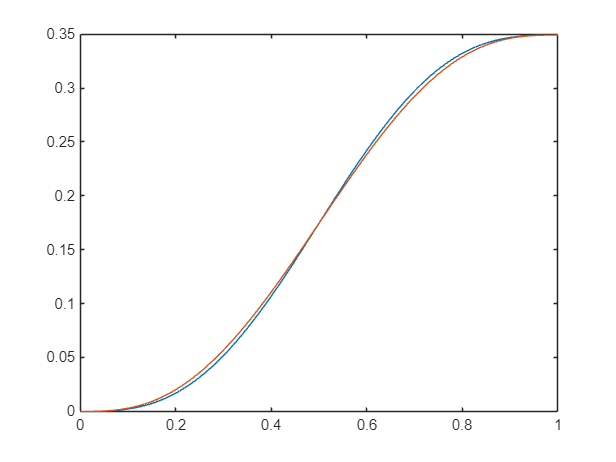

figure
plot(tau,theta_sin)
hold on
plot(tau, theta_q5)

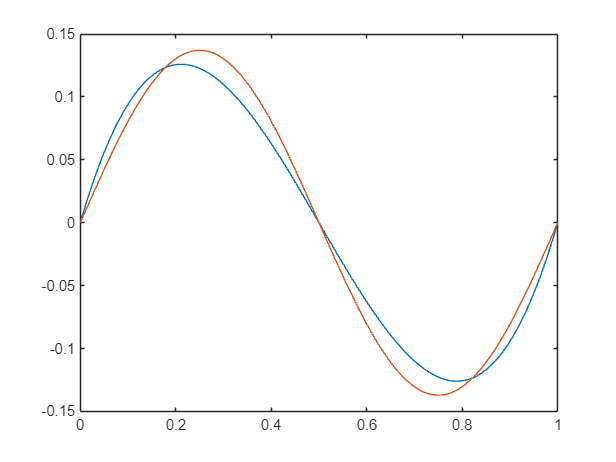


figure
plot(tau, alpha_q5)
hold on
plot(tau, alpha_sin)

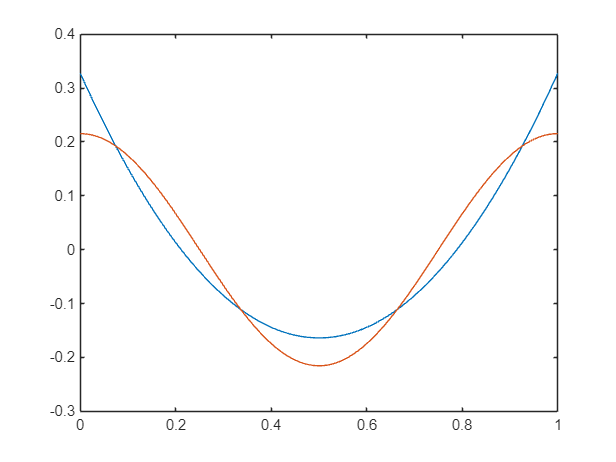


figure
plot(tau, j_q5);
hold on
plot(tau, j_sin)